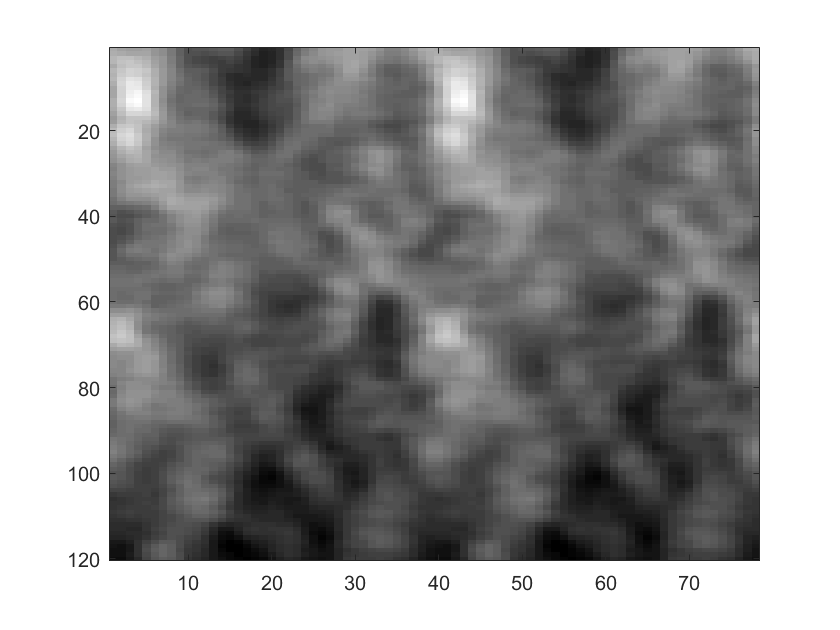

fname1 = '..\testing\testKymographs\SM1_JF-549_500ms.exp_50.Power_100x6s_3_MMStack_Pos0.ome_denoise_reg_ring15_kymoWrap.tif';
fname2 = '..\testing\testKymographs\180327_Sam1_1mW_RingHiLO_1_MMStack_Pos0.ome_denoise_reg_ring1_kymoWrap.tif';

im = imread(fname2);
im(end,:)=[];%remove the last black (non-data) row
imagesc(im);
colormap gray

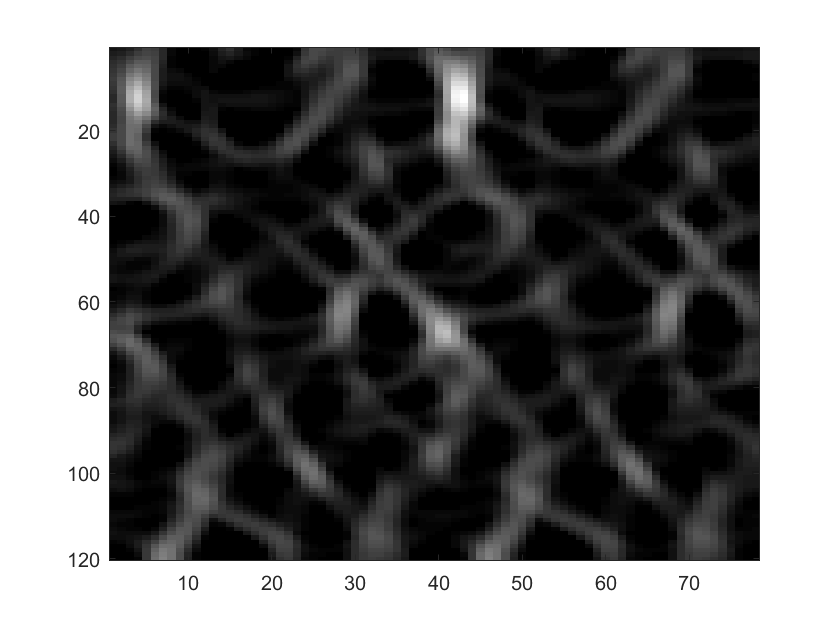


blurSigma = 2;
[ridgeBW ridge nms nms_8con  ] = cannyridgefilter(im,blurSigma);
imagesc(ridge);
colormap gray;

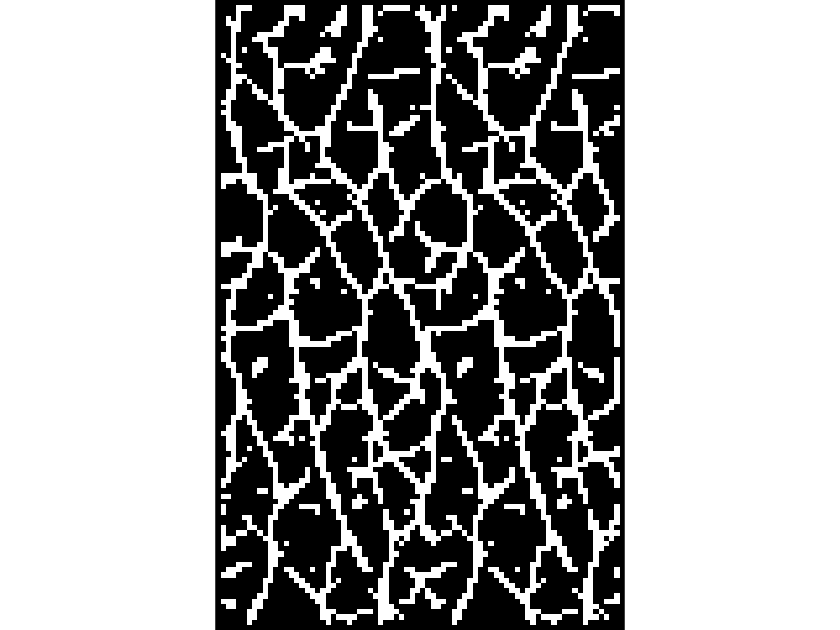

imshow(ridgeBW)

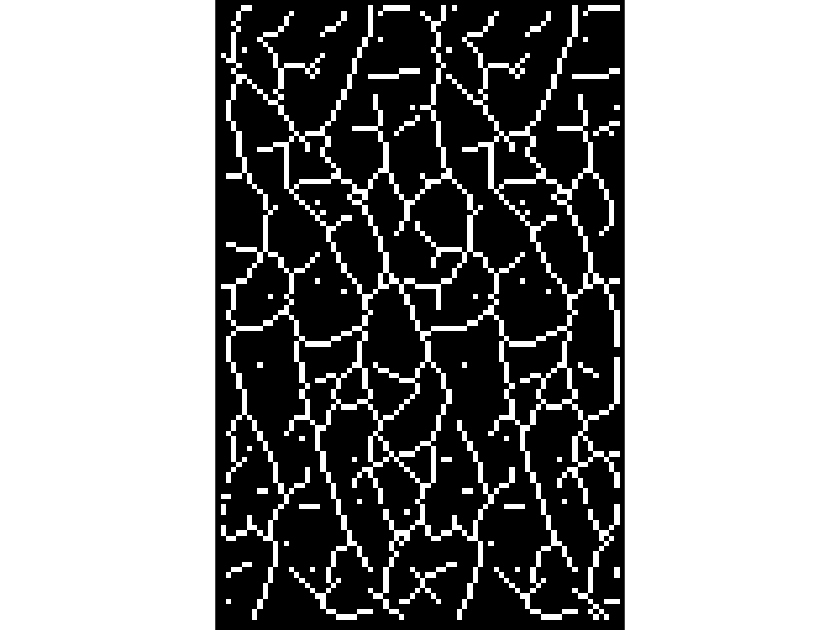

ridgeBWSkel=bwskel(ridgeBW);
imshow(ridgeBWSkel);

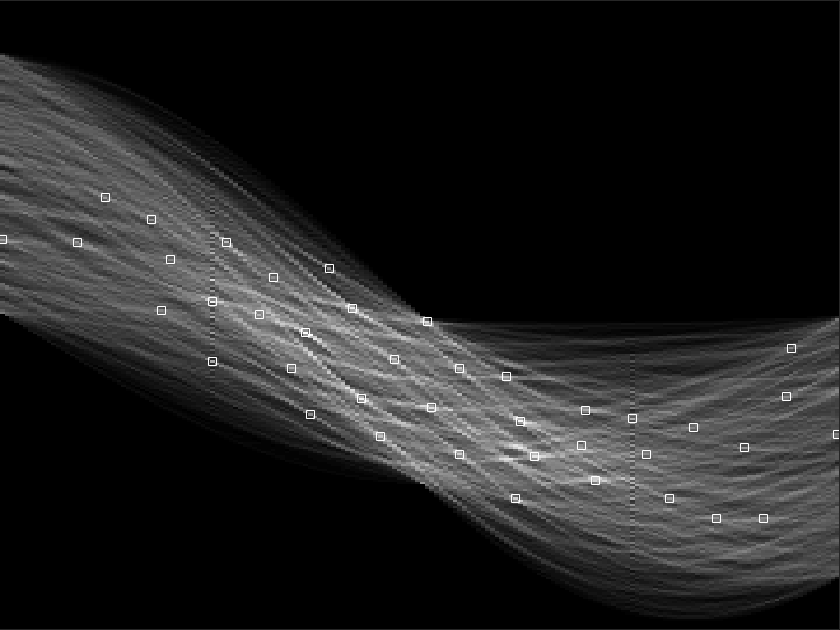


[H,T,R] = hough(ridgeBW);
 figure
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
MAXPEAK =1000;
thresh = ceil(0.5*max(H(:)));
suppressNHood = [21 11];%rho theta
suppressNHood = size(H)/10; %rho theta
suppressNHood = max(2*ceil(suppressNHood/2) + 1, 1);
P  = houghpeaks(H,MAXPEAK,'threshold',thresh,'NHoodSize', suppressNHood);
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

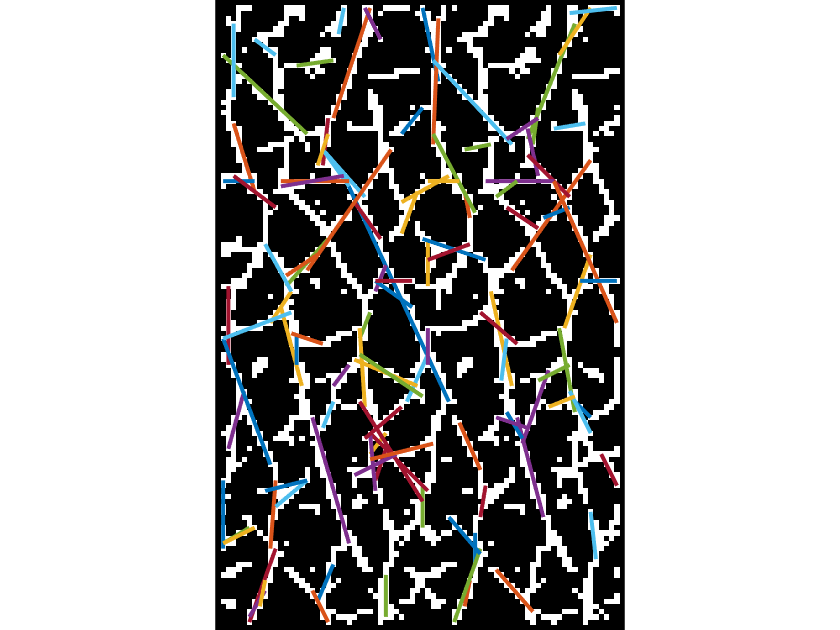

lines = houghlines(ridgeBW,T,R,P,'FillGap',3,'MinLength',5);
figure, imshow(ridgeBW), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2);

%    % Plot beginnings and ends of lines
%    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
%    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

hough line detection looks pretty crap

what about returning to : the fourier filtering plus temporal median subtraction to get the static component?

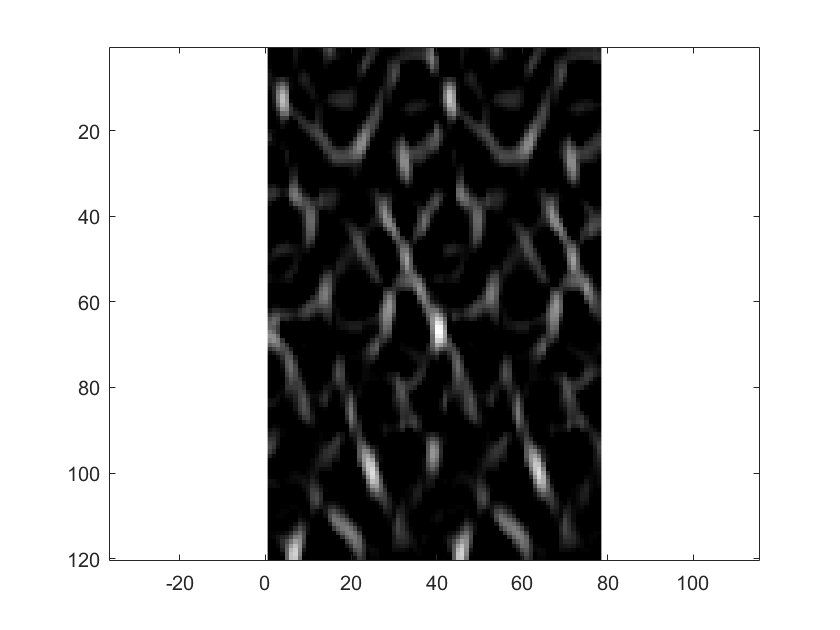

[fg bg] = kymoMedFilter(ridge,30);
fg(fg<0)=0;
imagesc(fg);colormap gray;axis equal;

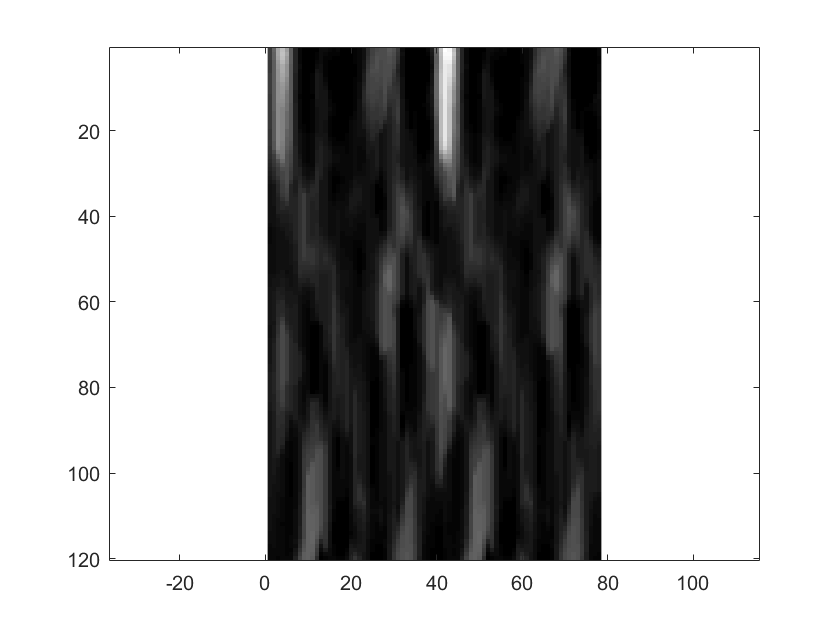

imagesc(bg);colormap gray;axis equal;

Looks pretty distorting of the data.

The ridge filter looks great but how to extract the lines from the image??